# Final Exam

# Course 2025-26 Q1

## Problem 2

Answer the following questions about the two dimensional finite element method. The equation to be considered is


$$-\frac{\partial}{\partial x}\left(%
a_{11}\frac{\partial u}{\partial x}
\right) - \frac{\partial}{\partial y}\left(
a_{22}\frac{\partial u}{\partial y}
\right) = 0, 
$$


with the domain and values $a_{11}$, $a_{22$ provided in the questions.

**Note.** Questions sets (a,b,c,d) and (f,g) are independent problems. Questions a, b, c, d and f do not require any prior computations.

### Part (a)

(2 points) Consider the meshed domain: `nodes = [0,0;1,0;1,1;2,0]`, `elem = [1,2,3;3,2,4]` with  $a_{11} = a_{22} = 1$ in $\Omega^{1}$ and, $a_{11} = 3$, $a_{22} = 1$ in $\Omega^{2}$. The value $K_{1,2}$ in the assembled matrix is

- `-3/2`

- `-1/2 `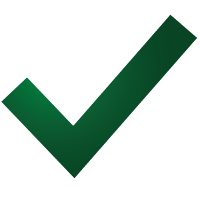

-  `-2`

- `-1`

- `Leave it empty (no penalty)`

#### Solution

According to the matrices `nodes `and `elem`, it follows that the meshed domain is the one shown in the figure below,

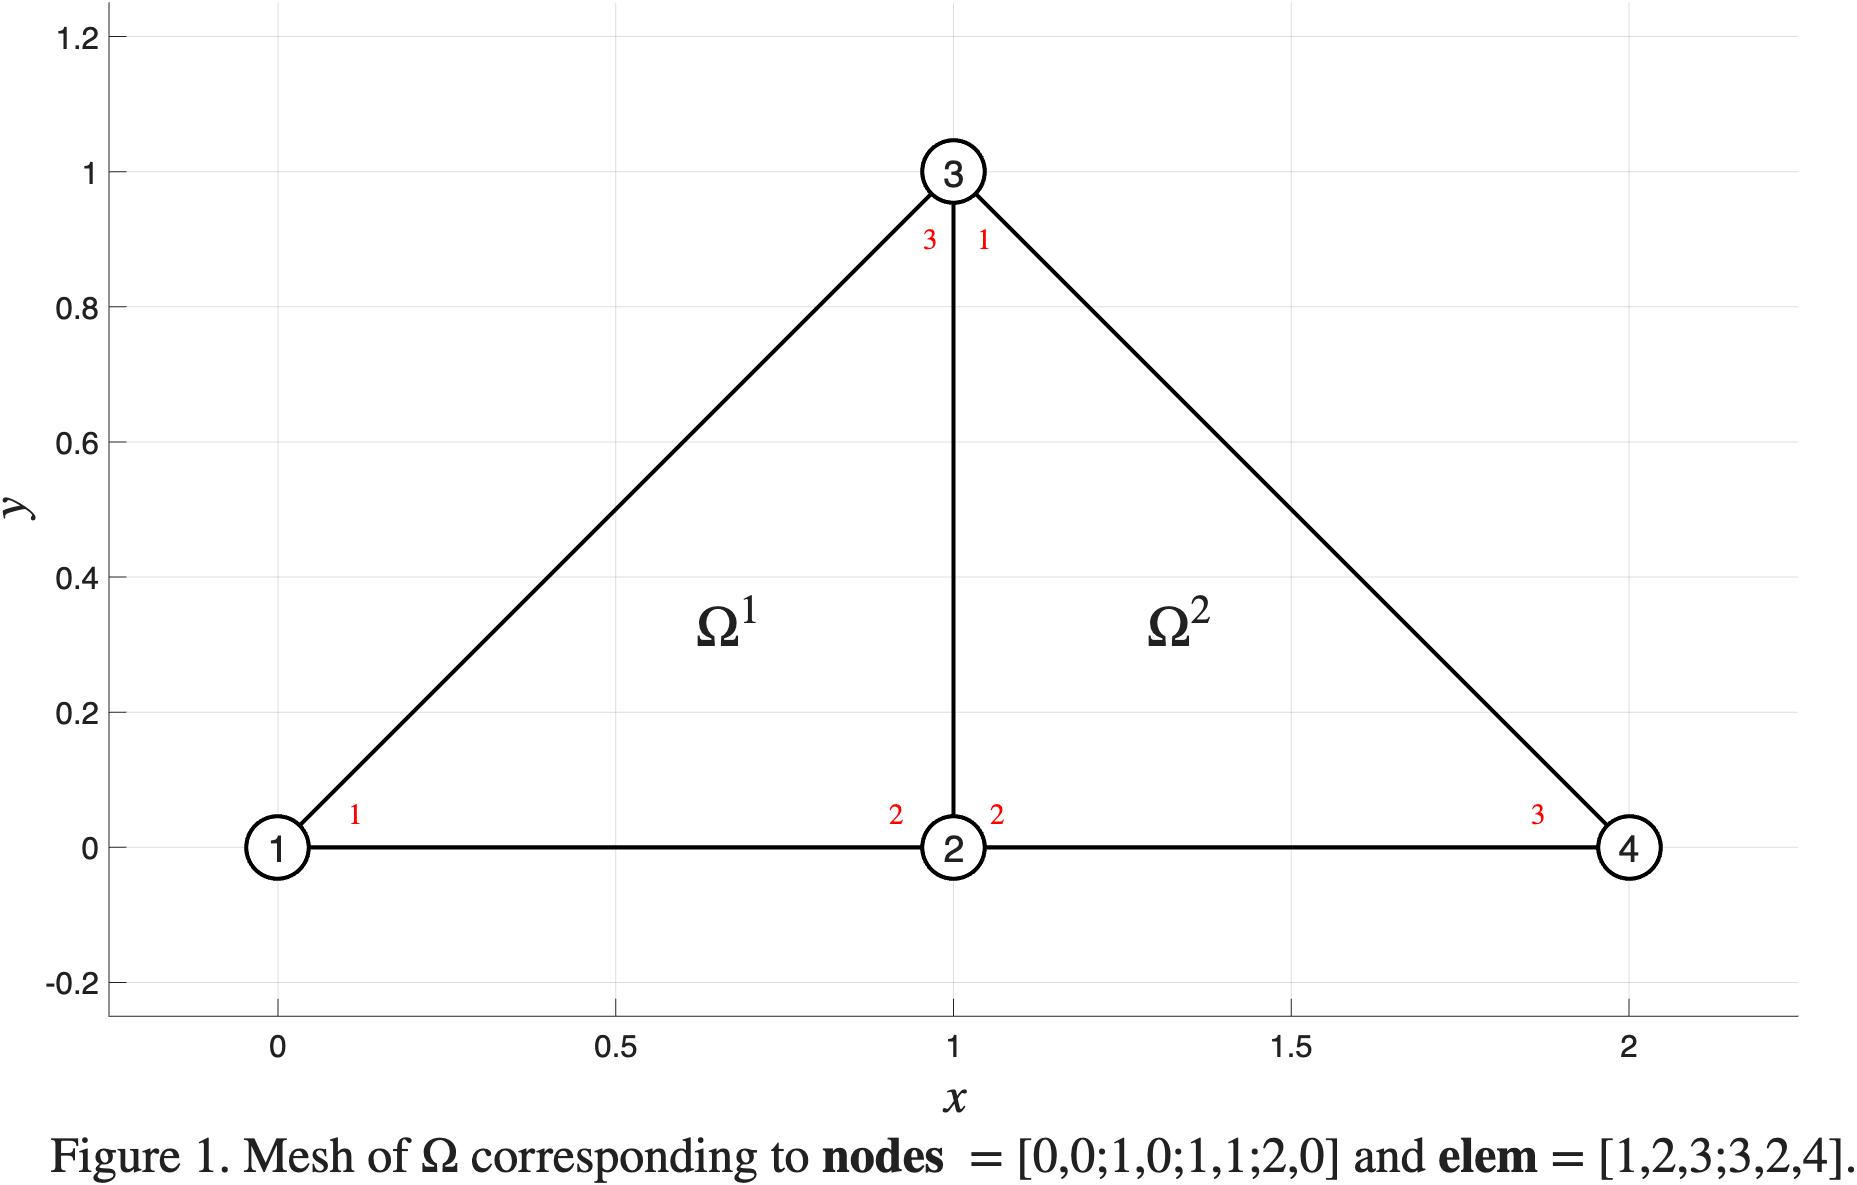

`Since `$a^{1}_{11} = a^{1}_{22} = 1$, $a^{1}_{12} = a^{1}_{21} = a^{1}_{00} = 0$. To find the local stiffness matrix of element $\Omega^{1}$ we can use the formulas for the Poisson equafion on right triangles, i.e. (see the [course slides](https://numfactory.upc.edu/numfactory/subjects/FEM/FEM/theory/T2-MN-FEM2D.pdf), pàg. 28, available at prof. Antonio Susin's site [Numerical Factory](https://numfactory.upc.edu/blog/)), 

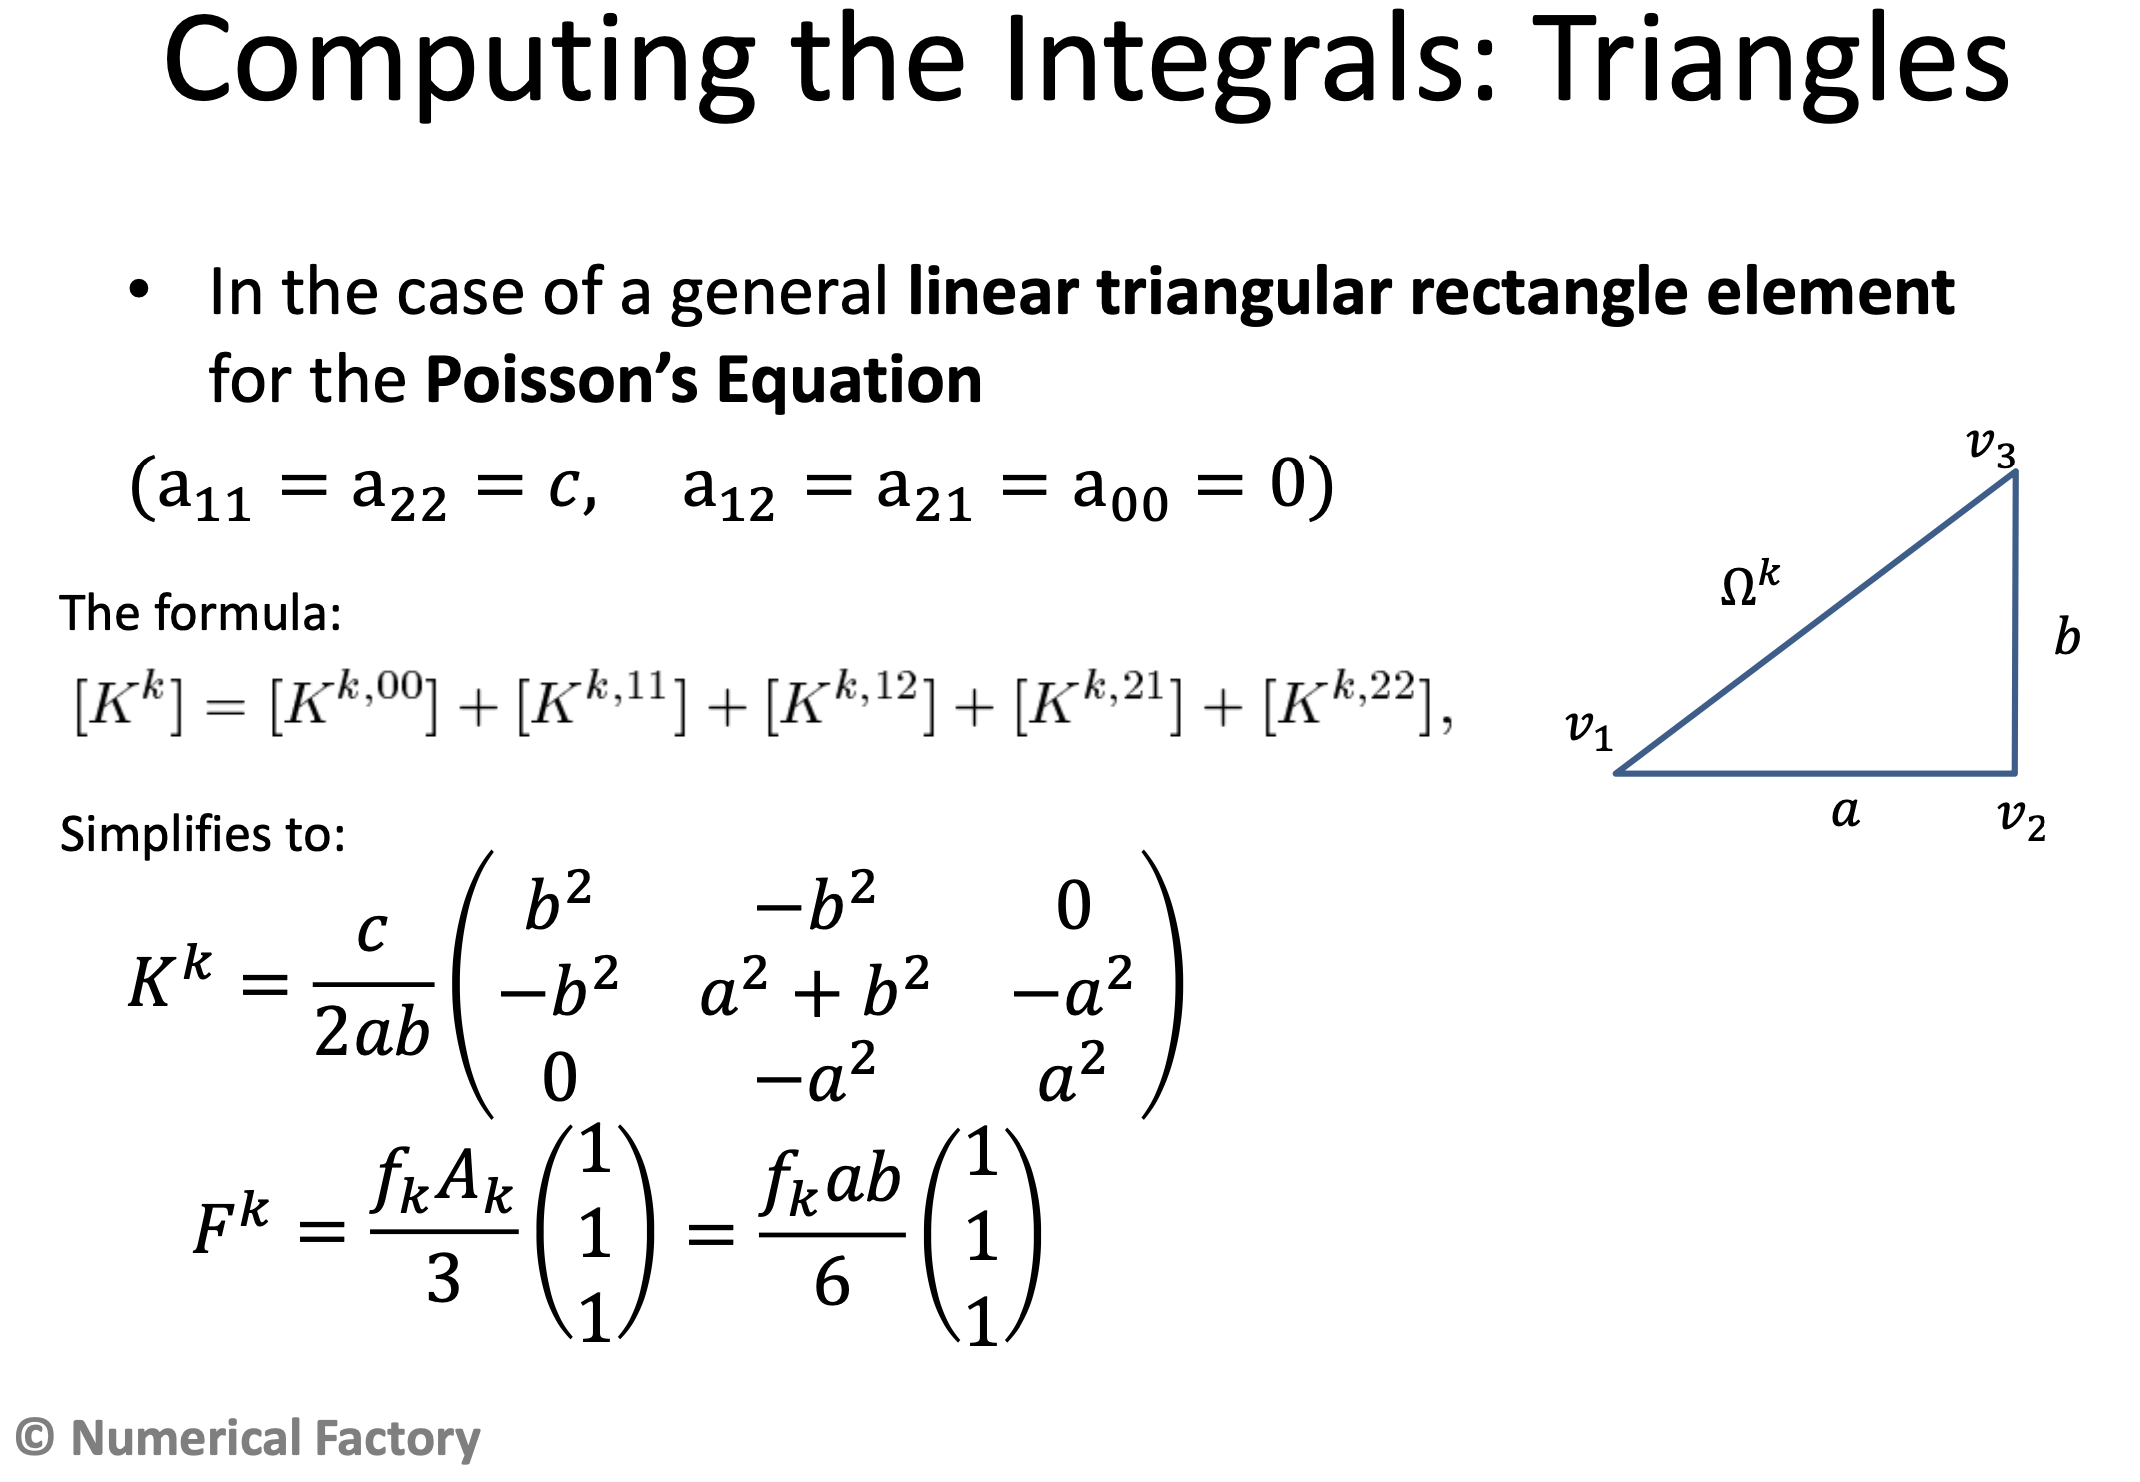

substituting $c = a^{1}_{11} = a^{1}_{22} = 1$, $a = b = 1$ in the above formulas yields:

$K^{1} = \frac{c}{2ab}
\left(\begin{array}{ccc}
b^{2} & -b^{2} & 0\\
-b^{2} & a^{2} + b^{2} & -a^{2}\\
0 & -a^{2} & a^{2}
\end{array}
\right) =
\frac{1}{2} 
\left(\begin{array}{rr}
1 & -1 & 0\\
-1 & 2 & -1\\
0 & -1 & 1
\end{array}
\right)$.

Moreover, note that $F^{1} = \left(\begin{array}{c} 0\\ 0\\ 0\end{array}\right)$, since $f^{1}\equiv 0$.

Nevertheless, to compute the stiffness matrix of $\Omega^{2}$, we cannot use the above formulas for, though $a_{12} = a_{21} = a_{00} \equiv 0$ and $a_{11}$, $a_{22}$ are both constant, now $a_{11}\equiv 3\ne a_{22}\equiv 1$, so we need to go to the (more "general") formulas for triangular elements with constant coefficients, i.e., 

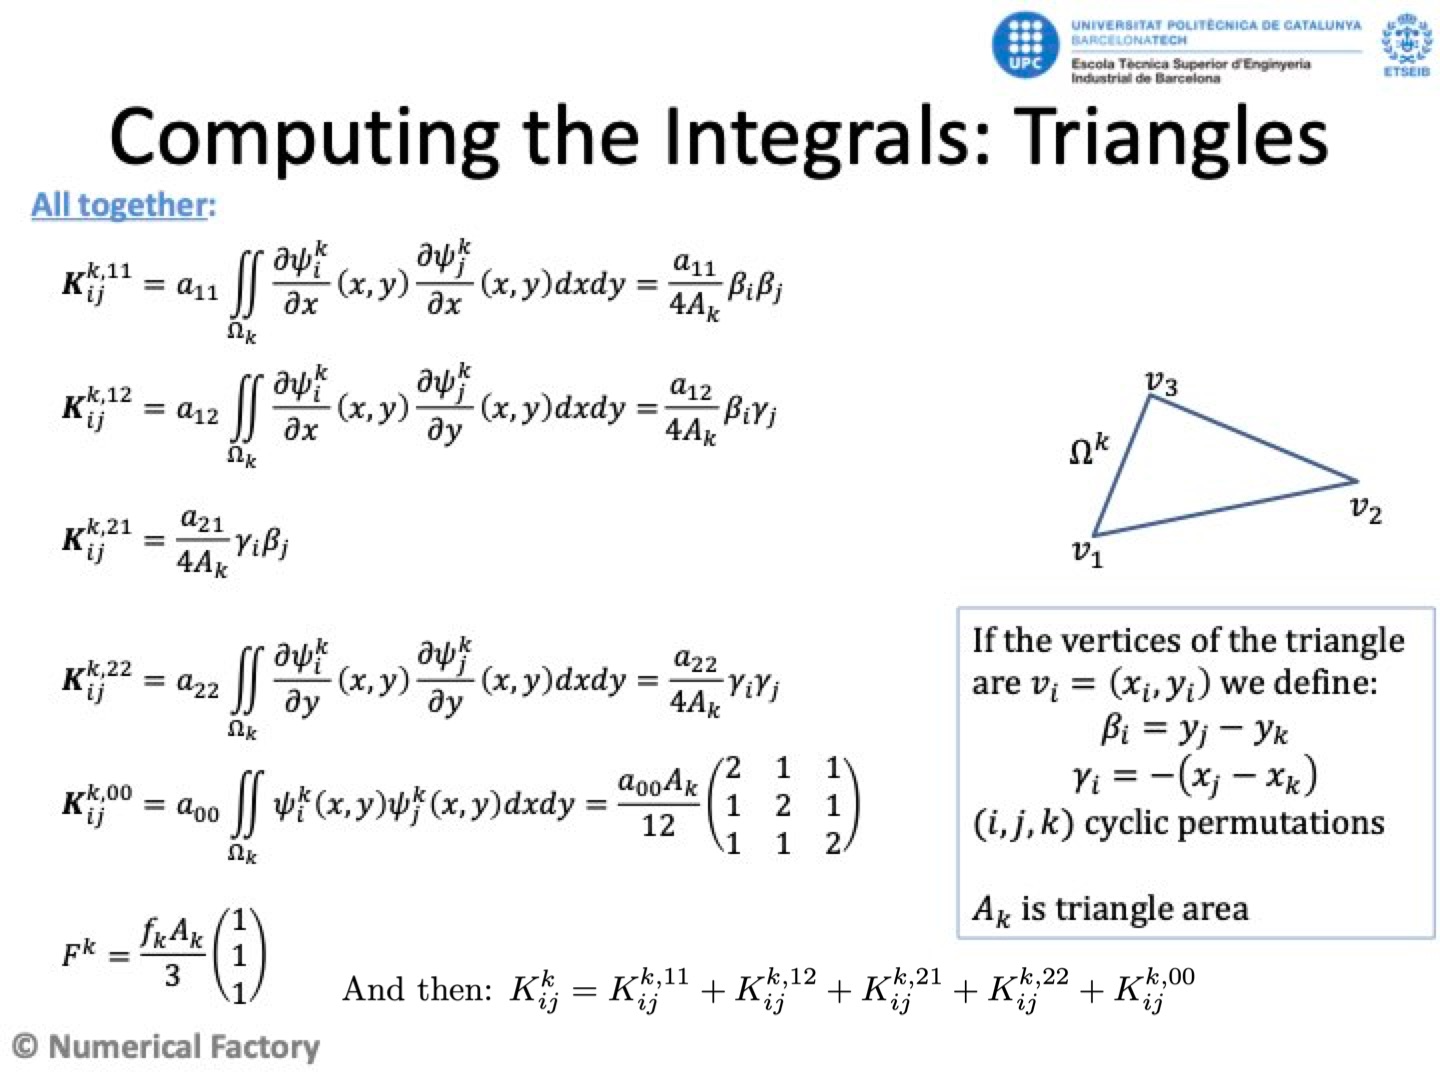

(see the [course slides](https://numfactory.upc.edu/numfactory/subjects/FEM/FEM/theory/T2-MN-FEM2D.pdf), pàg. 27, at prof. Antonio Susin's [Numerical Factory](https://numfactory.upc.edu/blog/)), In our example ($k = 2$),  $a^{2}_{11} \equiv 3$. $a^{2}_{12} = a^{2}_{21} = a^{2}_{00} \equiv 0$, $a^{2}_{22} \equiv 1$, $f^{2}\equiv 0$,  and $A_{2} = \frac{1}{2}$, so


$$\begin{array}{c}
\begin{array}{c|cc|cc|c|c}
i & x^{2}_{i} & y^{2}_{i} & j & k &
 \beta^{2}_{i} = y^{2}_{j} - y^{2}_{k} &
\gamma^{2}_{i} = -(x^{2}_{j} - x^{2}_{k})  \\ \hline 
1 & 1 & 1 & 2 & 3 & \ 0 & \ 1\\ 
2 & 1 & 0 & 3 & 1 & -1 & -1\\
3 &  2 & 0 & 1 & 2 & \ 1 & \ 0 \\ 
\end{array}\\  \\
\begin{array}{rcl}
K^{2,11} \!\!\!\! & = &\!\!\!\!
\frac{a^{2}_{11}}{4A_{2}}\left(
\begin{array}{r}
\beta^{2}_{1}\\
\beta^{2}_{2}\\
\beta^{2}_{3}
\end{array}
\right)
\left(\begin{array}{ccc}
\beta^{2}_{1} &
\beta^{2}_{2} &
\beta^{2}_{3}
\end{array}\right) = \frac{3}{2}
\left(
\begin{array}{r}
0\\
-1\\
1
\end{array}
\right)
\left(\begin{array}{ccc}
0 &
-1 &
1
\end{array}\right) 
\end{array} = 
\frac{1}{2}\left(
\begin{array}{rrr}
0 & 0 & 0\\
0 & 3 & -3\\
0 & -3 & 3
\end{array}
\right),
\\
\begin{array}{rcl}
K^{2,22} \!\!\!\! & = &\!\!\!\!
\frac{a^{2}_{22}}{4A_{2}}\left(
\begin{array}{r}
\gamma^{2}_{1}\\
\gamma^{2}_{2}\\
\gamma^{2}_{3}
\end{array}
\right)
\left(\begin{array}{ccc}
\gamma^{2}_{1} &
\gamma^{2}_{2} &
\gamma^{2}_{3}
\end{array}\right) = \frac{1}{2}
\left(
\begin{array}{r}
1\\
-1\\
0
\end{array}
\right)
\left(\begin{array}{ccc}
1 &
-1 &
0
\end{array}\right) =
\frac{1}{2}\left(\begin{array}{rrr}
1 & -1 & 0\\
-1 & 1 & 0\\
0 & 0 & 0 
\end{array}
\right).
\end{array}

\end{array}$$


whereas, obviously, $K^{2,12} = K^{2,21} = K^{2,00} = 0$. Hence, 


$$K^{2} = K^{2,11} + K^{2,22} = \frac{1}{2}\left(
\begin{array}{rrr}
0 & 0 & 0\\
0 & 3 & -3\\
0 & -3 & 3
\end{array}
\right) +
\frac{1}{2}\left(\begin{array}{rrr}
1 & -1 & 0\\
-1 & 1 & 0\\
0 & 0 & 0 
\end{array}
\right) = 
\frac{1}{2}\left(
\begin{array}{rrr}
1 & -1 & 0\\
-1 & 4 & -3\\
0 & -3 & 3
\end{array}
\right).$$


Moreover, $F^{2} = \left(\begin{array}{c} 0\\ 0\\ 0\end{array}\right)$, since $f^{2}\equiv 0$. Finally, assembling the local stiffness matrices $K^{1}$ and $K^{2}$, we get for the global stiffness matrix,


$$K =\left(
\begin{array}{cccc}
K^{1}_{1,1} & K^{1}_{1,2} & K^{1}_{1,3} & 0\\
K^1_{2,1} & K^1_{2,2} + K^2_{2,2} & K^1_{2,3} + K^2_{2,1} & K^2_{2,3} \\
K^{1}_{3,1} & K^{1}_{3,2} + K^{2}_{1,2} & K^{1}_{3,3} + K^{2}_{1,1} & K^{2}_{1,3} \\
0 & K^{2}_{3,2} & K^{2}_{3,1} & K^{2}_{3,3}
\end{array}
\right)
=
 \frac{1}{2}\left(\begin{array}{rrrr}
1 & -1 & 0 & 0\\
-1 & 6 & -2 & -3\\
0 & -2 & 2 & 0\\
0 & -3 & 0 & 3
\end{array}
\right).$$


Moreover, assembling the force vector is, trivially, $F = \left(\begin{array}{c} F^{1}_{1}\\ F_{2}^{1} + F^{2}_{2}\\ F^{1}_{3} + F^{2}_{1}\\ F^{2}_{3}\end{array}\right) = \left(\begin{array}{c} 0^{}_{}\\ 0^{}_{}\\ 0^{}_{}\\ 0^{}_{}\end{array}\right)$. Therefore, we see that $K_{2,2} = 3$.

**Remark:** Note that we are asked *only for component* $K_{1,2}$ so, actually as $K_{1,2} = K^{1}_{1,2}$, we just need to compute the components $K^{1}_{1,2}$ of $\Omega^{1}$, hence


$$K_{2,2} = K^{1}_{1,2} = -\frac{1}{2}.$$


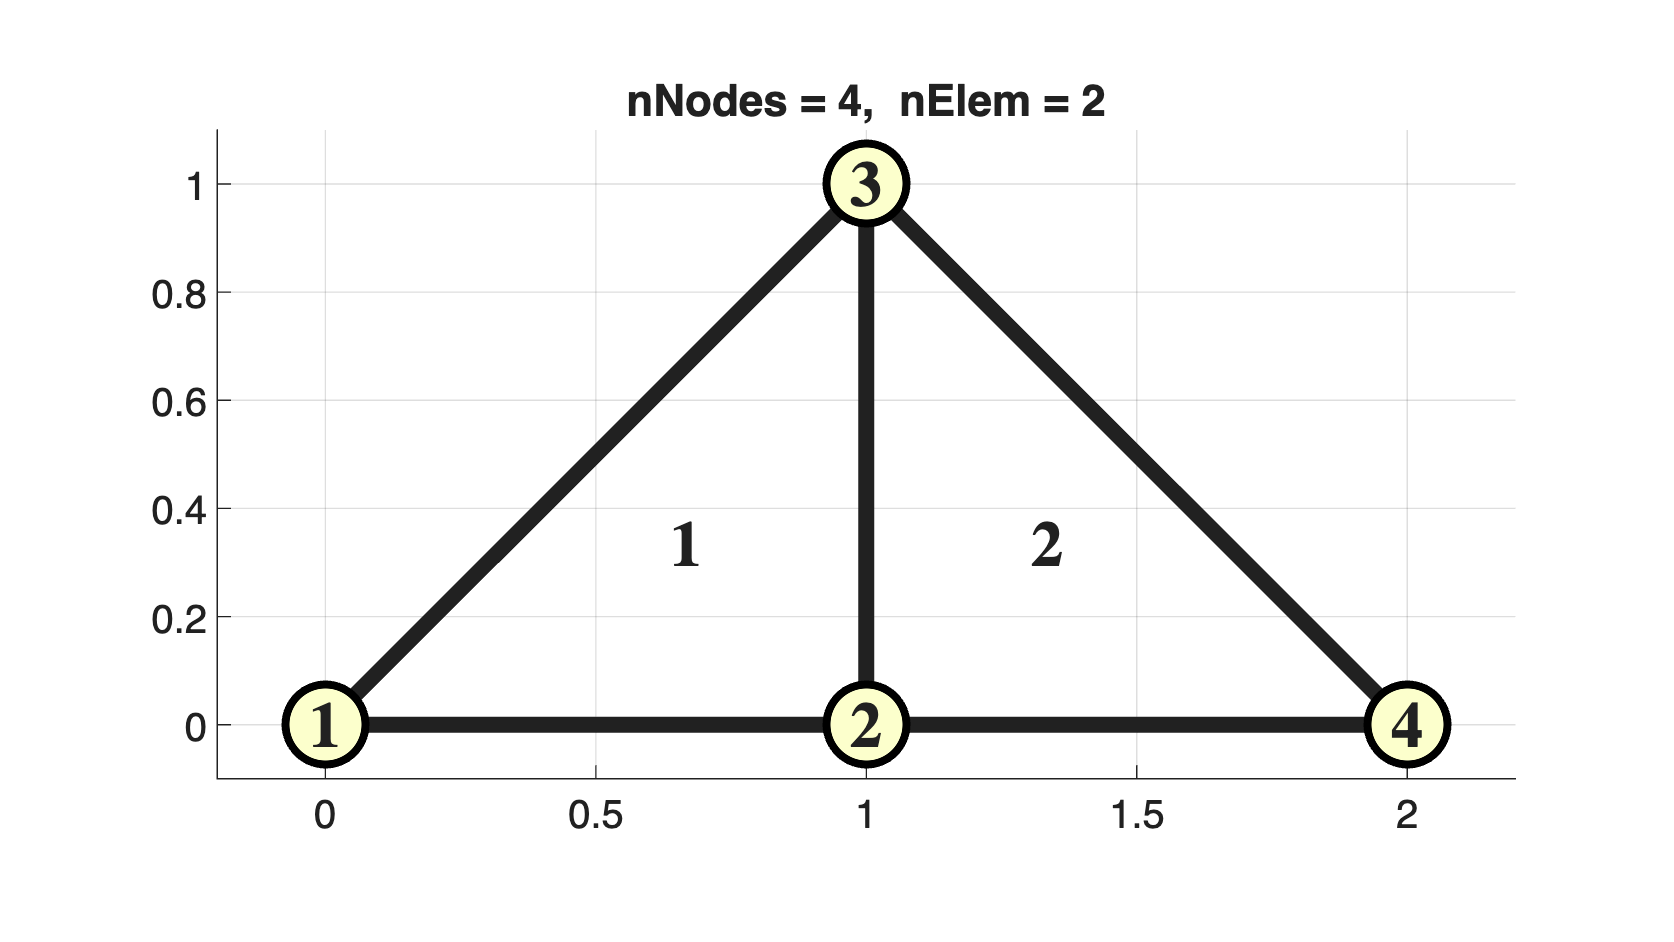

clearvars
close all

format long e
format compact

relativePathToLib = './../lib'; addpath(relativePathToLib);

nodes = [0,0; 1,0; 1,1; 2,0];
elem = [1,2,3; 3,2,4];

h = 1;% length of edge 1-2 (edge 1 of element 1),
      %           edge 2-3 (edge 2 of element 1, or
      %                    (edge 1 of element 2)
      %           edge 2-4 (edge 2 of element 2)

% Element 1
a11 = 1; a12 = 0; a21 = 0; a22 = 1; a00 = 0; f = 0;
coeff1 = [a11,a12,a21,a22,a00,f];
% Element 2
a11 = 3; a12 = 0; a21 = 0; a22 = 1; a00 = 0; f = 0;
coeff2 = [a11,a12,a21,a22,a00,f];

coeFuy21 = -1; % in edge 1-2 uy21 = -u
uInf = 0;      % in edge 1-2

%Constant B.C.               
uy24 = -2;     % u_{y} along the edge 2-4
U1 = 1;
U3 = 0;
U4 = 0;

p = [1/2,1]; %Point for part (f)
a11f = 3;    %Coefficient for part (g) 
 
%Plot the mesh
numbering = 1;
fig1 = figure();
plotElements(nodes, elem, numbering)

Compute the assembled matrix

%Compute the assembled matrix
beta = zeros(3,1); gamma = zeros(3,1);
vectOnes = [1; 1; 1];
vertexs = nodes(elem(1,:),:);

Area = 0.5*det([vectOnes,vertexs]);

beta(1) = vertexs(2,2) - vertexs(3,2);
beta(2) = vertexs(3,2) - vertexs(1,2);
beta(3) = vertexs(1,2) - vertexs(2,2);

gamma(1) = -(vertexs(2,1) - vertexs(3,1));
gamma(2) = -(vertexs(3,1) - vertexs(1,1));
gamma(3) = -(vertexs(1,1) - vertexs(2,1));


$K^{1}$:

K1 = 0.25*(coeff1(1)*(beta*beta') + coeff1(4)*(gamma*gamma'))/Area;
fprintf("%14.5e%14.5e%14.5e\n",K1')

   5.00000e-01  -5.00000e-01   0.00000e+00
  -5.00000e-01   1.00000e+00  -5.00000e-01
   0.00000e+00  -5.00000e-01   5.00000e-01



clear beta gamma Area;
beta = zeros(3,1); gamma = zeros(3,1);
vertexs = nodes(elem(2,:),:);

Area = 0.5*det([vectOnes,vertexs]);

beta(1) = vertexs(2,2) - vertexs(3,2);
beta(2) = vertexs(3,2) - vertexs(1,2);
beta(3) = vertexs(1,2) - vertexs(2,2);

gamma(1) = -(vertexs(2,1) - vertexs(3,1));
gamma(2) = -(vertexs(3,1) - vertexs(1,1));
gamma(3) = -(vertexs(1,1) - vertexs(2,1));

$K^{2}$:

K2 = 0.25*(coeff2(1)*(beta*beta') + coeff2(4)*(gamma*gamma'))/Area;
fprintf("%14.5e%14.5e%14.5e\n",K2')

   5.00000e-01  -5.00000e-01   0.00000e+00
  -5.00000e-01   2.00000e+00  -1.50000e+00
   0.00000e+00  -1.50000e+00   1.50000e+00


Assembled matrix $K$:

%Assemble the local matrices
K = zeros(4,4);
rows = [elem(1,1), elem(1,2), elem(1,3)]; cols = rows;
K(rows,cols) = K1;
rows = [elem(2,1), elem(2,2), elem(2,3)]; cols = rows;
K(rows,cols) = K(rows,cols)+K2;
fprintf("%14.5e%14.5e%14.5e%14.5e\n",K')

   5.00000e-01  -5.00000e-01   0.00000e+00   0.00000e+00
  -5.00000e-01   3.00000e+00  -1.00000e+00  -1.50000e+00
   0.00000e+00  -1.00000e+00   1.00000e+00   0.00000e+00
   0.00000e+00  -1.50000e+00   0.00000e+00   1.50000e+00


$K_{1,2}$:

fprintf('(a) K(1,2) = %s\n',strtrim(rats(K(1,2))))

(a) K(1,2) = -1/2


#### Part (b)

(1 point) The value $K_{2,2}$ in the assembled system is

- Leave it empty (no penalty)

- `3 `

- `6`

- `5`

- 4

#### Solution

The component $K_{2,2}$ of the assembled matrix is given by,


$$K_{2,2} = K^{1}_{2,2} + K^{2}_{2,2} = \frac{c}{2 a b}\left( a^{2} + b^{2} \right) + 
    \frac{1}{4 A_{2}}\left(a^{2}_{1,1}\beta^{2}_{2}\beta^{2}_{2} + a^{2}_{2,2}\gamma^{2}_{2}\gamma^{2}_{2}\right) 
= \frac{1}{2}\left(1^{2} + 1^{2}\right) + \frac{1}{2}\left( 3\times (-1)^{2} + 1\times (-1)^{2}\right)
= 1 + 2 = 3.$$


fprintf('(b) K(2,2) = %s\n',strtrim(rats(K(2,2))))

(b) K(2,2) = 3


## Part (c)

(2 points)  Continue in the same setting. Consider the boundary conditions $u(x,y) = 1 - y$ in $1-3$; $u(x,y)\equiv 0$ in $3-4$; $\frac{\partial u}{\partial y}(x,y) = -u$ in $1-2$ and, $\frac{\partial u}{\partial y}(x,y) \equiv -2$ in $2-4$. Given that $Q^{1}_{2,1} = AU_{2} + B$, the value of $A$ is

- Leave it empty (no penalty)

- `2/3`

- `1/3 `

- `1`

- `4/3`

#### Solution

Computation of $Q^{1}_{2,1}$. The given B.C. are: $u(x,y) = 1- y$ in $1-3$; $u(x,y) \equiv 0$ in $3-4$; $\frac{\partial u}{\partial y}(x,y) = -u$ in $1-2$ and $\frac{\partial u}{\partial y}(x,y) = -2$ in $2-4$. 

The flow $q_{n,1}^{1}$ through $\Gamma^{1}_{1}$, the edge 1 of element $\Omega^{1}$ (edge $1-2$ in the *global* numbering) is given by,


$$q_{n,1}^{1} (s) = \left\langle\left(\begin{array}{cc} a^{1}_{1,1} & 0\\ 0 & a^{1}_{2,2}\end{array}\right)\left(\begin{array}{c} u_{x}(s,0)\\
 u_{y}(s,0)\end{array}\right), \left(\begin{array}{r} 0\\ -1\end{array}\right)
\right\rangle =
-a^{1}_{2,2} u_{y}(s,0) = u(s,0),\qquad 0 \le s \le h_{1}^{1} = 1$$


(we recall that $a^{1}_{1,1} = a^{1}_{2,2} \equiv 1$) where we've used the B.C. on the edge $\Gamma^{1}_{1}$, i.e., $u_{y}(x,y) = \frac{\partial u}{\partial y}(x,y) = -u(x,y)$ for 

$(x,y)\in \Gamma^{1}_{1} = \left\{(s,0)\in\mathbb{R}^{2}: 0\le s\le h_{1}^{1} = 1\right\}$,

and note that $q^{1}_{n,1}(s) = u(s,0)$ for $0\le s\le h^{1}_{1} = 1$ can be though of as a *convection*  B.C. with $\beta = -1$and $u_{\infty} = 0$.  Hence,  to find $Q^{1}_{2,1}$ we apply the formula,


$$Q^{1}_{2,1} = -\beta h^{1}_{1}\left(\frac{U^{1}_{1}}{6} + \frac{U^{1}_{2}}{3}\right) + \beta h^{1}_{1}\frac{U_{\infty}}{2} =
 -\beta h^{1}_{1}\left(\frac{U_{1}}{6} + \frac{U_{2}}{3}\right) + \beta h^{1}_{1}\frac{U_{\infty}}{2}
$$


juat with $\beta = -1$, $U_{\infty} = 0$. Besides, taking into account the boundary condition on the edge $\Gamma^{1}_{3}$ (edge $1-3$ in the global numbering), $u(x,y) = 1-y$, we know that $u(0,0) = 1 - 0 = 1$(note that node $1$of element $\Omega^{1}$, also node $1$ in the global numbering, belongs to edge $\Gamma^{1}_{3}$. Therefore,


$$Q^{1}_{2.1} = A U_{2} + B = \frac{U_{2}}{3} + \frac{1}{6}$$
   

and indetifying coefficients in this last equation it is readily seen that$A = \frac{1}{3}$, and $B= \frac{1}{6}$.

A = -coeFuy21 * coeff1(4) * h/3; B = -coeFuy21 * coeff1(4) * h * U1/6;
fprintf(['(c) A = %s,\n','    B = %s.\n'],strtrim(rats(A)), strtrim(rats(B)))

(c) A = 1/3,
    B = 1/6.


## Part (d)

 (1 point) With the same boundary conditions as in \(c\). The value of $Q^{2}_{2,2}$ is

- `3`

- 1 

- Leave it empty (no penalty)

- 2

- `3/2`

#### Solution

Computation of $Q^{2}_{2,2}$. The flow $q_{n,2}^{2}$ through $\Gamma^{2}_{2}$, the edge $2$ of element $\Omega^{2}$ (edge $2-4$ in the *global* numbering) is given by,


$$q_{n,2}^{2} (s) = \left\langle\left(\begin{array}{cc} a^{2}_{11} & 0\\ 0 & a^{2}_{2,2}\end{array}\right)\left(\begin{array}{c} u_{x}(1+s,0)\\
 u_{y}(1+s,0)\end{array}\right), \left(\begin{array}{r} 0\\ -1\end{array}\right)
\right\rangle =
-a^{2}_{22} u_{y}(1+s,0) = -u_{y}(1+s,0) = 2,\qquad 0 \le s \le h_{2}^{2} = 1$$


(we recall that $a^{2}_{11} \equiv 3$, $a^{2}_{22} \equiv 1$) where we've used the B.C. on the edge $\Gamma^{2}_{2}$ (edge $2-4$ in the *global *numbering), i.e., $u_{y}(x,y) = \frac{\partial u}{\partial y}(x,y) = -2$ for 

$(x,y)\in \Gamma^{2}_{2} = \left\{(1+s,0)\in\mathbb{R}^{2}: 0\le s\le h_{2}^{2} = 1\right\}$,

so $q^{2}_{n,2}\equiv 2$ (i.e. is a *constant* flow). Therefore,

$Q^{2}_{2,2} = h^{2}_{2}\frac{q^{2}_{n,2}}{2} = 1$.

Q222 = -uy24 * coeff2(4) * h/2; %"Flow" on node 2 of element 2 due to the
                                %flow through edge 2 of the element
fprintf('(d) Q{2}(2,2) = %s\n',strtrim(rats(Q222)))

(d) Q{2}(2,2) = 1


#### Part (e)

(1 point) The approximate value of $u(1,0)$ for the problem defined in (a)--(c) is

- Leave it empty (no penalty)

- `1`

- `17/4`

- `5/8 `

- `17/20`

#### Solution

The approximate value of $u(1,0)$ is given by the displacement of the second global node, $U_{2}$, i.e., $u(1,0)\approx U_{2}$. After setting the boundary conditions, the reduced system to solve is made of with just $1$ equation, namely

$K_{2,1} U_{1} + K_{2,2}U_{2} + K_{2,3} U_{3} K_{2,4} U_{4} = Q_{2} + F_{2}$,

with $U_{1} = 1$ (see above, part (c)) $U_{3} = U_{4} = 0$ since, according to the B.C., along the edge to which (global) nodes $3$ and $4$ belong, edge $\Gamma^{2}_{3}$  (edge $3-4$ in the *global* numbering) is $u\equiv 0$. Furtermore $K_{2,1} = K_{1,2} = -\frac{1}{2}$ (already found in (a)), $K_{2,2} = 3$ (already found in (b)) and, in what concerns the r.h.s. of the equation we have, on the one hand that $F_{2} \equiv 0$ (no heat source, i.e., $f\equiv 0$, at the r.h.s. of the PDE,  the global load. vector, $F\equiv 0$) and, on the other hand

$Q_{2} = Q^{1}_{2,1} + Q^{2}_{2,2} = \frac{U_{2}}{3} + \frac{1}{6} + 1 = \frac{U_{3}}{3} + \frac{7}{6}$.

Substituting these values, the above system casts as,

$-\frac{1}{2} + 3 U_{2} = \frac{U_{2}}{3} + \frac{7}{6}$,

Which can be rearranged at once into the standart form, we mean

 
$$\left(3-\frac{1}{3}\right) U_{2} = \frac{7}{6} + \frac{1}{2} \Longleftrightarrow
\frac{8}{3} U_{2} = \frac{10}{6}$$


and therefore, $U_{2} = \frac{5}{8}$. 

%B.C.
Q = zeros(4,1);
F = zeros(4,1);
u = zeros(4,1);

%Natural
K(2,2) = K(2,2) - A; %Add the convetion term to the (global) stiffness matrix
Q(2) = B + Q222;

%Essential
freeNods = 2;
fixedNods = [1,3,4];

u(1) = U1;
u(3) = U3;
u(4) = U4;

%Reduced system
Fm = Q(freeNods) + F(freeNods) - K(freeNods,fixedNods)*u(fixedNods);
Km = K(freeNods,freeNods);

% Solve the reduced system for the unknown displacements
um = Km \ Fm;
u(freeNods) = um;
fprintf('(e) u(1,0) %c U(2) = %s\n', char(0x2248), strtrim(rats(u(2))))

(e) u(1,0) ≈ U(2) = 5/8


##  Part (f)

(2 points) Consider the rectangular element $\Omega^{k} = [0,6]\times[0,2]$ with local node number $1$ in $(0,0)$. The value of $\psi^{k}_{3}\left(1/2,1\right)$is

- `1/8`

- `1/12`

- Leave it empty (no penalty)

- `1/24 `

- `1/4`

#### Solution

First we plot the element, assuming node $1$ is at the origin $(x,y) = (0,0)$.  Trivially:

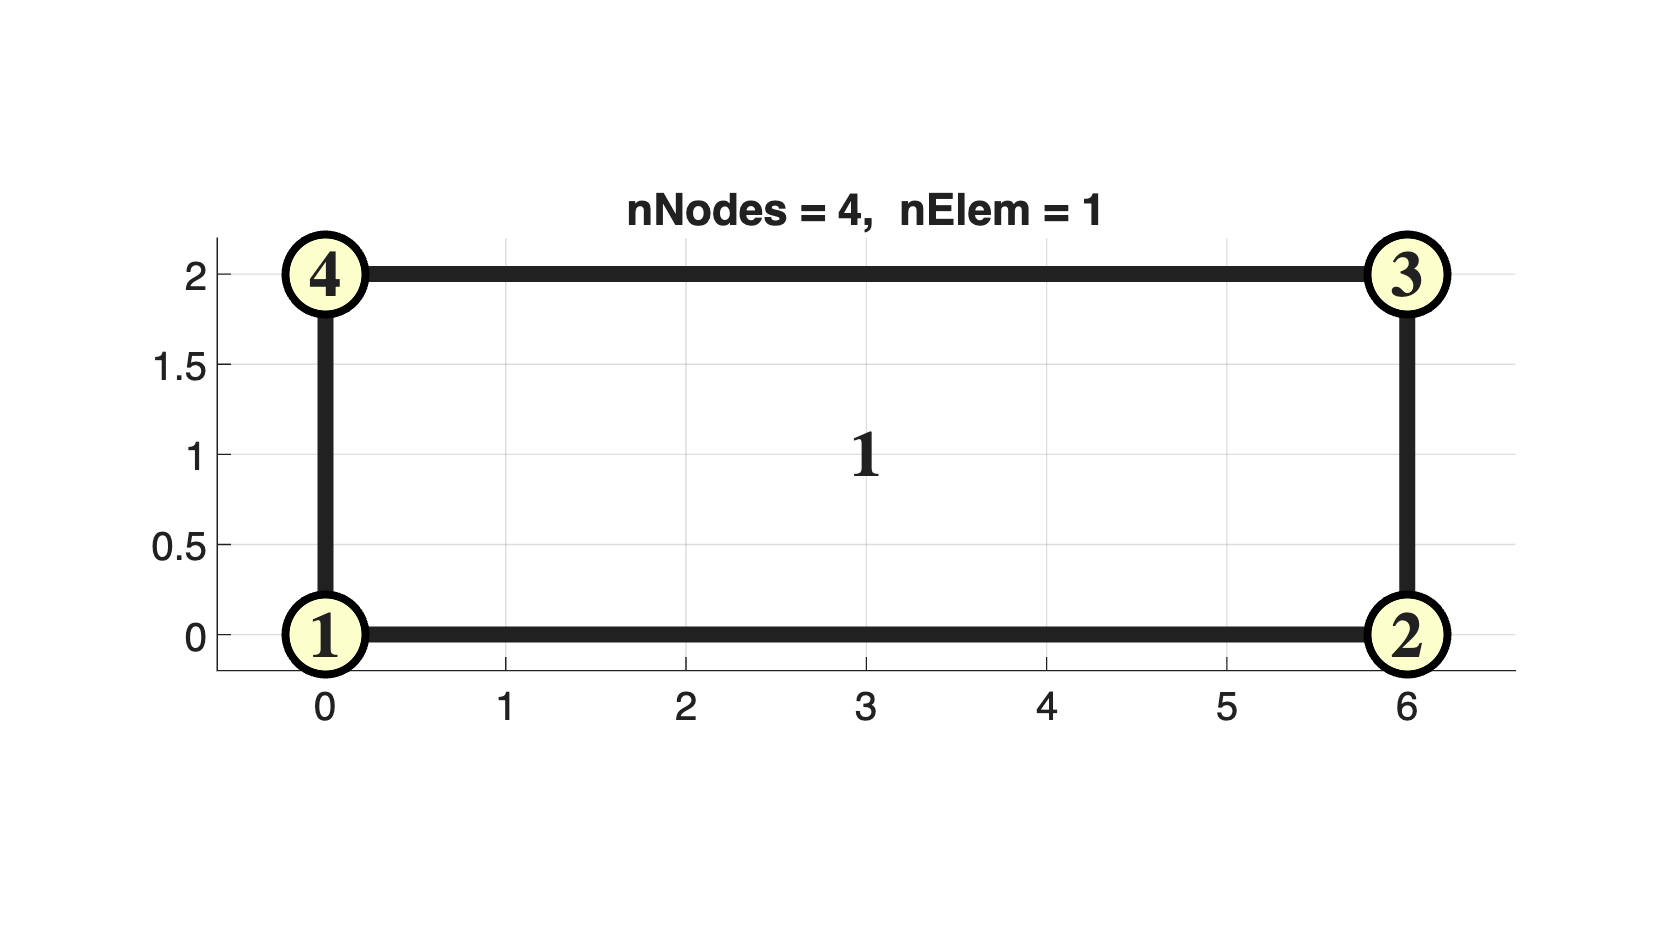

clear nodes elem
syms x y a22 
nodes = [0,0; 6,0; 6,2; 0,2]; numNodes = size(nodes,1); 
elem = [1,2,3,4]; numElem = size(elem,1);
fig2 = figure();

plotElements(nodes, elem, 1)

xlim([-0.60 6.60])
ylim([-0.20 2.20])

We shall use the formulas for the shape functions $\psi^{k}_{i}(x,y)$, $i=1,2,3,4$, when the element $\Omega^{k}$ is a bilinear rectangle, i.e., 

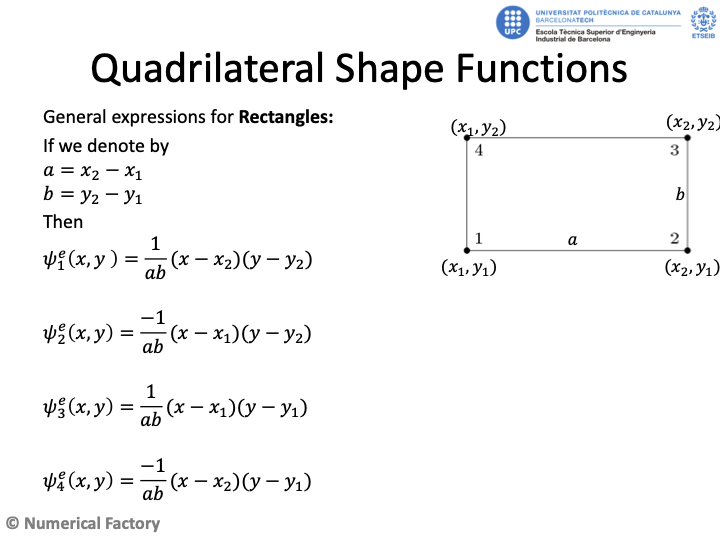

(see the [course slides](https://numfactory.upc.edu/numfactory/subjects/FEM/Interpolation/theory/T1-MN-Interpolation-ShapeFunctions.pdf), pàgines 32, 33, at prof. Antonio Susin's [Numerical Factory](https://numfactory.upc.edu/blog/)). As the vertexs of the given rectangle are


$$p^{k}_{1} = (X_{1}^{k},Y_{1}^{k}) = (0.0),\quad 
p^{k}_{2} = (X^{k}_{2},Y^{k}_{1}) = (6,0),\\
p^{k}_{3} = (X^{k}_{2},Y^{k}_{2}) = (6,2),\quad
p^{k}_{4} = (X^{k}_{1},Y^{k}_{2}) = (0,2),\quad$$


application of the formula for $i = 3$ for $\psi^{k}_{3}(x,y)$ yields


$$\psi^{k}_{3}(x,y) = \frac{\left(x-X^{k}_{1}\right)\left(y- Y^{k}_{1}\right)}%
{\left(X^{k}_{2}-X^{k}_{1}\right)\left(Y^{k}_{2}- Y^{k}_{1}\right)} =
\frac{xy}{12}.$$


Therefore, $\psi^{k}_{3}\left(\frac{1}{2},1\right) = \frac{1}{24}$.

a = nodes(2,1) - nodes(1,1);
b = nodes(4,2) - nodes(1,2);
Psik3(x,y) = x*y / (a*b)

$$Psik3(x, y) = \frac{x\,y}{12}$$

fprintf('(f) Psik3(%s,%s) = %s\n',...
    strtrim(rats(p(1))), strtrim(rats(p(2))), ...
    strtrim(rats(Psik3(p(1),p(2)))))

(f) Psik3(1/2,1) = 1/24


## Part (g)

(1 point) Consider $a_{11}(x,y)\equiv 3$ and $a_{22}(x,y) = x + 1$. The value of $K^{k}_{3,3}$ for $\Omega^{k}$ in (f) is 

- `34/6`

- `35/6 `

- `37/6`

- `38/6`

- Leave it empty (no penalty)

#### Solution

$a_{1,1} ^{k}\equiv 3$ (const), $a_{2,2}^{k}(x,y) = x+1$. Compute $K_{3,3}^{k}$. We shall use the formulas,


$$\begin{array}{c}
K^{k,11}_{3,3} = \int\!\!\!\!\!\!\int_{\Omega^{k}} a^{k}_{1,1}(x,y)\frac{\partial \psi^{k}_{3}}{\partial x}(x,y)\frac{\partial\psi^{k}_{3}}{\partial x}(x,y)\,\mathrm{d}x \mathrm{d} y,\\
K^{k,22}_{3,3} = \int\!\!\!\!\!\!\int_{\Omega^{k}} a^{k}_{2,2}(x,y)\frac{\partial \psi^{k}_{3}}{\partial y}(x,y)\frac{\partial\psi^{k}_{3}}{\partial y}(x,y)\,\mathrm{d}x \mathrm{d} y,
\end{array}$$


 which in this case at point give

which, for the given functions, can be computed as iterated integrals on the rectangle $\Omega^{k}$. Indeed


$$K^{k,11}_{3,3} = \frac{3}{144}\int_{0}^{6}\mathrm{d} x\!\int_{0}^{2}  y^{2}\,\mathrm{d}y = \frac{18}{144}\int_{0}^{2} y^{2}\,
\mathrm{d} y\\% 
\qquad = \frac{18}{144}\left(\frac{y^{3}}{3}\right|_{0}^{2}%
= \frac{18\times 8}{144\times 3} = \frac{2^{4}\times 3^{2}}{2^{4}\times 3^{3}} = \frac{1}{3},
$$


and


$$K^{k,22}_{3,3} = \frac{1}{144}\int_{0}^{2}\mathrm{d} y\!\int_{0}^{6} (1+x) x^{2}\,\mathrm{d}x = \frac{1}{72}\int_{0}^{6} \left(x^{2} + x^{3}\right)\,
\mathrm{d} x\\% 
\qquad = \frac{1}{72} \left(\frac{x^{3}}{3} + \frac{x^{4}}{4}\right|^{6}_{0}%
= \frac{2^{3}\times 3^{3}}{2^{3}\times 3^{3}} + \frac{2^{4}\times 3^{4}}{2^{5}\cdot 3^{2} } = 1+  \frac{9}{2} = \frac{11}{2}.$$


So finally, $K^{k}_{3,3}$ is given by the sum


$$K^{k}_{3,3} = K^{k,11}_{3,3} + K^{k,22}_{3,3} = \frac{1}{3} + \frac{11}{2} = \frac{35}{6}.$$


a11 = a11f;
a22(x,y) = 1+x;
dxPsik3(x,y) = diff(Psik3,x);
dyPsik3(x,y) = diff(Psik3,y);
K1133 = int(int(a11*dxPsik3*dxPsik3,y,0,2),x,0,6);
K2233 = int(int(a22*dyPsik3*dyPsik3,y,0,2),x,0,6);
%Finally
K33 = K1133 + K2233;
fprintf('(g) K(3,3) = %s\n',strtrim(rats(K33)))

(g) K(3,3) = 35/6
